# **Image analysis: Project 2 RANSAC**

**Thanisorn Sriudomporn**

thasri@student.chalmers.se

clc;
clear;

Modify addine_test_case

This section is to modify the function affine_test_case to be able to add gaussian noise to the measurement.

% outlier_rate = 0.6;
% sigma = 1;
% N = 150000; %Number of data
% [pts, pts_tilde, A_true, t_true] = affine_test_case(N,outlier_rate,sigma);
% 
% %Test LS
% [A_Ls,t_Ls] = least_squares_affine(pts, pts_tilde);

Make function for average_residual_lgths

% threshold = 10;
% average_residual_lgths_inlier = average_residual_lgths(A_true,t_true,pts,pts_tilde,threshold);


Modify RANSAC and test with and without Local optimization

% d = 1;
% tic
% [A_w_local,t_w_local,k_loop_w_local,nbr_inlier_w_local] = ransac_fit_affine(pts, pts_tilde,d, threshold,true);
% average_residual_lgths_inlier_with_local = average_residual_lgths(A_w_local,t_w_local,pts,pts_tilde,threshold);
% toc
% tic
% [A_wo_local,t_wo_local,k_loop_wo_local,nbr_inlier_w0_local] = ransac_fit_affine(pts, pts_tilde,d, threshold,false);
% average_residual_lgths_inlier_without_local = average_residual_lgths(A_wo_local,t_wo_local,pts,pts_tilde,threshold);
% toc
% disp('done')

1.1-1.2 The Tdd test for various outlier ratio

*This section might take around 10 minutes or more to finish*

N = 1000; %Number of data
sigma = 1; %Standard deviation
threshold = 5.99*sigma;
warning('off');
result_11_k_loop = zeros(4,10);
result_11_runtime = zeros(4,10);
result_11_number_of_inlier = zeros(4,10);
outlier_rates = linspace(0,0.9,10);
for j = 1:10
    outlier_rate = outlier_rates(j);
    [pts, pts_tilde, A_true, t_true] = affine_test_case(N,outlier_rate,sigma);
    for d = 0:3
       runtime_temp = zeros(1,10);
       k_loop_temp = zeros(1,10);
       nbr_inlier_temp = zeros(1,10);
       for i = 1:10
           tic
           [A_w_local,t_w_local,k_loop_w_local,nbr_inlier_w_local] = ransac_fit_affine(pts, pts_tilde,d, threshold,false);
           runtime_temp(i) = toc;
           k_loop_temp(i) = k_loop_w_local;
           nbr_inlier_temp(i) = nbr_inlier_w_local;
       end
       runtime_avg_temp = sum(runtime_temp)/10;
       k_loop_avg_temp = sum(k_loop_temp)/10;
       nbr_inlier_avg_temp = sum(nbr_inlier_temp)/10;
       result_11_runtime(d+1,j) = runtime_avg_temp;
       result_11_k_loop(d+1,j) = k_loop_avg_temp;
       result_11_number_of_inlier(d+1,j) = nbr_inlier_avg_temp;
    end
end


2.1 The local optimazation test for various outlier ratio

N = 150000; %Number of data
sigma = 1;
threshold = 5.99*sigma;
d = 1;
outlier_rates = linspace(0,0.6,7);
warning('off');
result_21_runtime = zeros(1,7);
result_21_k_loop = zeros(1,7);
result_21_nbr_inlier = zeros(1,7);
result_21_avg_residual_length = zeros(1,7);
result_21_runtime_local = zeros(1,7);
result_21_k_loop_local = zeros(1,7);
result_21_nbr_inlier_local = zeros(1,7);
result_21_avg_residual_length_local = zeros(1,7);

for i = 1:7
    runtime_temp = zeros(1,10);
    k_loop_temp = zeros(1,10);
    nbr_inlier_temp = zeros(1,10);
    avg_r = zeros(1,10);
    runtime_temp_local = zeros(1,10);
    k_loop_temp_local = zeros(1,10);
    nbr_inlier_temp_local = zeros(1,10);
    avg_r_local = zeros(1,10);
    %Generate data
    [pts, pts_tilde, A_true, t_true] = affine_test_case(N,outlier_rates(i),sigma);
    for j = 1:10
        %RANSAC with out local optimization
        tic
        [A_wo_local,t_wo_local,k_loop_wo_local,nbr_inlier_wo_local] = ransac_fit_affine(pts, pts_tilde,d, threshold,false);
        runtime_temp(j) = toc;
        k_loop_temp(j) = k_loop_wo_local;
        nbr_inlier_temp(j) = nbr_inlier_wo_local;
        avg_r_temp = average_residual_lgths(A_wo_local,t_wo_local,pts,pts_tilde,threshold);
        avg_r(j) = avg_r_temp;
        
        %RANSAC with local optimization
        tic
        [A_w_local,t_w_local,k_loop_w_local,nbr_inlier_w_local] = ransac_fit_affine(pts, pts_tilde,d, threshold,true);
        runtime_temp_local(j) = toc;
        k_loop_temp_local(j) = k_loop_w_local;
        nbr_inlier_temp_local(j) = nbr_inlier_w_local;
        avg_r_local_temp = average_residual_lgths(A_w_local,t_w_local,pts,pts_tilde,threshold);
        avg_r_local(j) = avg_r_local_temp;        
    end
    result_21_runtime(i) = sum(runtime_temp)/10;
    result_21_k_loop(i) = sum(k_loop_temp)/10;
    result_21_nbr_inlier(i) = sum(nbr_inlier_temp)/10;
    result_21_avg_residual_length(i) = sum(avg_r)/10;
    result_21_runtime_local(i) = sum(runtime_temp_local)/10;
    result_21_k_loop_local(i) = sum(k_loop_temp_local)/10;
    result_21_nbr_inlier_local(i) = sum(nbr_inlier_temp_local)/10;
    result_21_avg_residual_length_local(i) = sum(avg_r_local)/10;
end


2.2 The local optimazation test for various standard variation

N = 150000; %Number of data
sigmas = [0.5 1 2 4 8 16];
thresholds = 5.99*sigmas;
d = 1;
outlier_rate = 0.4;
warning('off');
result_22_runtime = zeros(1,6);
result_22_k_loop = zeros(1,6);
result_22_nbr_inlier = zeros(1,6);
result_22_avg_residual_length = zeros(1,6);
result_22_runtime_local = zeros(1,6);
result_22_k_loop_local = zeros(1,6);
result_22_nbr_inlier_local = zeros(1,6);
result_22_avg_residual_length_local = zeros(1,6);

for i = 1:6
    runtime_temp = zeros(1,10);
    k_loop_temp = zeros(1,10);
    nbr_inlier_temp = zeros(1,10);
    avg_r = zeros(1,10);
    runtime_temp_local = zeros(1,10);
    k_loop_temp_local = zeros(1,10);
    nbr_inlier_temp_local = zeros(1,10);
    avg_r_local = zeros(1,10);
    threshold = thresholds(i);
    %Generate data
    [pts, pts_tilde, A_true, t_true] = affine_test_case(N,outlier_rate,sigmas(i));
    for j = 1:10
        %RANSAC with out local optimization
        tic
        [A_wo_local,t_wo_local,k_loop_wo_local,nbr_inlier_wo_local] = ransac_fit_affine(pts, pts_tilde,d, threshold,false);
        runtime_temp(j) = toc;
        k_loop_temp(j) = k_loop_wo_local;
        nbr_inlier_temp(j) = nbr_inlier_wo_local;
        avg_r_temp = average_residual_lgths(A_wo_local,t_wo_local,pts,pts_tilde,threshold);
        avg_r(j) = avg_r_temp;
        
        %RANSAC with local optimization
        tic
        [A_w_local,t_w_local,k_loop_w_local,nbr_inlier_w_local] = ransac_fit_affine(pts, pts_tilde,d, threshold,true);
        runtime_temp_local(j) = toc;
        k_loop_temp_local(j) = k_loop_w_local;
        nbr_inlier_temp_local(j) = nbr_inlier_w_local;
        avg_r_local_temp = average_residual_lgths(A_w_local,t_w_local,pts,pts_tilde,threshold);
        avg_r_local(j) = avg_r_local_temp;        
    end
    result_22_runtime(i) = sum(runtime_temp)/10;
    result_22_k_loop(i) = sum(k_loop_temp)/10;
    result_22_nbr_inlier(i) = sum(nbr_inlier_temp)/10;
    result_22_avg_residual_length(i) = sum(avg_r)/10;
    result_22_runtime_local(i) = sum(runtime_temp_local)/10;
    result_22_k_loop_local(i) = sum(k_loop_temp_local)/10;
    result_22_nbr_inlier_local(i) = sum(nbr_inlier_temp_local)/10;
    result_22_avg_residual_length_local(i) = sum(avg_r_local)/10;
end



Visualization for 1.1-1.2

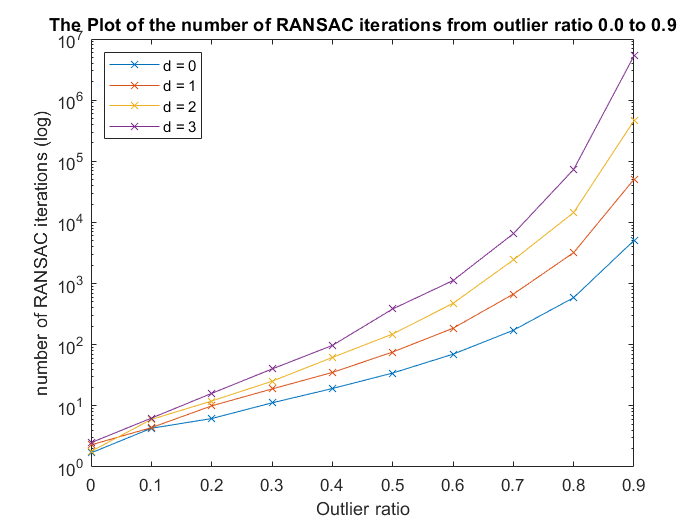

%One must run the previous section (1.1-1.2 The Tdd test for various outlier ratio)
%before runing this section
%or load these .mat
load('result_11_k_loop.mat')
load('result_11_number_of_inlier.mat')
load('result_11_runtime.mat')

%1.1


%1.1


figure(1)

outlier_rates_11 = linspace(0,0.9,10);
plot(outlier_rates_11,result_11_k_loop(1,:),'-x')
hold on
plot(outlier_rates_11,result_11_k_loop(2,:),'-x')
plot(outlier_rates_11,result_11_k_loop(3,:),'-x')
plot(outlier_rates_11,result_11_k_loop(4,:),'-x')
set(gca, 'YScale', 'log')
title('The Plot of the number of RANSAC iterations from outlier ratio 0.0 to 0.9')
xlabel('Outlier ratio') 
ylabel('number of RANSAC iterations (log)') 
legend({'d = 0','d = 1','d = 2','d = 3'},'Location','Northwest')
hold off

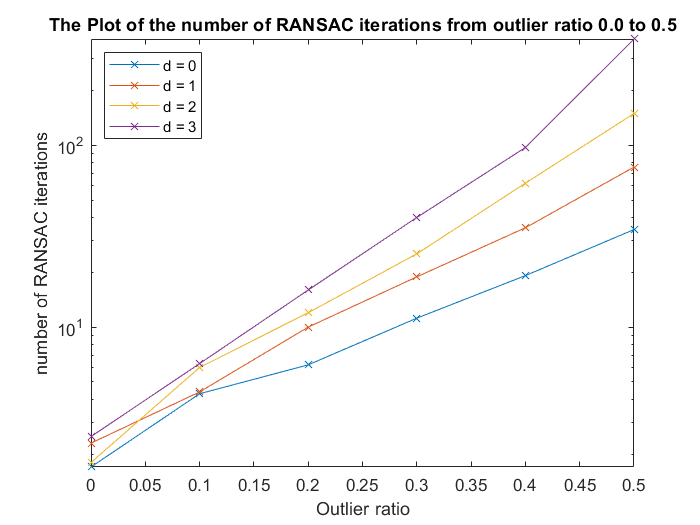




figure(2) %Zoom in from OR0.0 to OR0.3

plot(outlier_rates_11(1:6),result_11_k_loop(1,1:6),'-x')
hold on
plot(outlier_rates_11(1:6),result_11_k_loop(2,1:6),'-x')
plot(outlier_rates_11(1:6),result_11_k_loop(3,1:6),'-x')
plot(outlier_rates_11(1:6),result_11_k_loop(4,1:6),'-x')
set(gca, 'YScale', 'log')
title('The Plot of the number of RANSAC iterations from outlier ratio 0.0 to 0.5')
xlabel('Outlier ratio') 
ylabel('number of RANSAC iterations') 
legend({'d = 0','d = 1','d = 2','d = 3'},'Location','Northwest')
axis([0 0.5 0 inf])
hold off

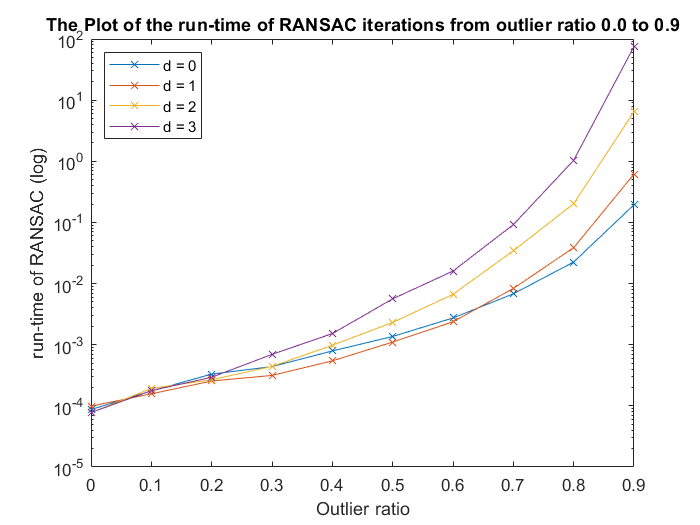


%1.2

figure(3)

plot(outlier_rates_11,result_11_runtime(1,:),'-x')
hold on
plot(outlier_rates_11,result_11_runtime(2,:),'-x')
plot(outlier_rates_11,result_11_runtime(3,:),'-x')
plot(outlier_rates_11,result_11_runtime(4,:),'-x')
set(gca, 'YScale', 'log')
title('The Plot of the run-time of RANSAC iterations from outlier ratio 0.0 to 0.9')
xlabel('Outlier ratio') 
ylabel('run-time of RANSAC (log)') 
legend({'d = 0','d = 1','d = 2','d = 3'},'Location','Northwest')
hold off

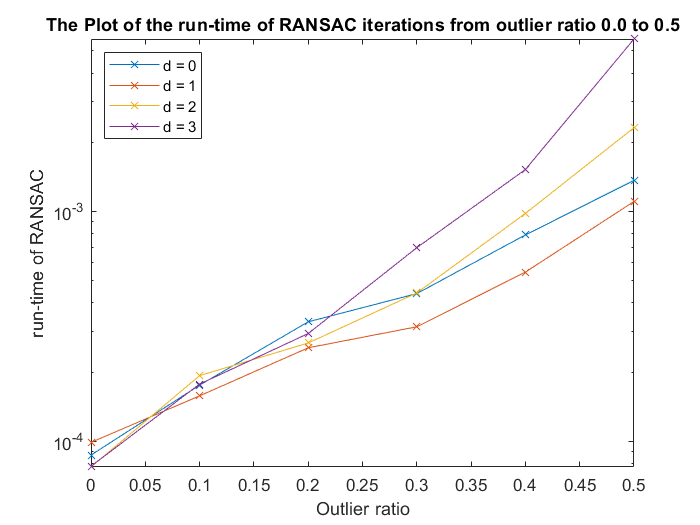



figure(4)%Zoom in from OR0.0 to OR0.5


plot(outlier_rates_11(1:6),result_11_runtime(1,1:6),'-x')
hold on
plot(outlier_rates_11(1:6),result_11_runtime(2,1:6),'-x')
plot(outlier_rates_11(1:6),result_11_runtime(3,1:6),'-x')
plot(outlier_rates_11(1:6),result_11_runtime(4,1:6),'-x')
set(gca, 'YScale', 'log')
title('The Plot of the run-time of RANSAC iterations from outlier ratio 0.0 to 0.5')
xlabel('Outlier ratio') 
ylabel('run-time of RANSAC') 
legend({'d = 0','d = 1','d = 2','d = 3'},'Location','Northwest')
axis([0 0.5 0 inf])
hold off

Theoretical part

Testing modified local optimization.

N = 150000; %Number of data
sigma = 1;
threshold = 10;
d = 1;
outlier_rates = linspace(0,0.6,7);
warning('off');
result_t_runtime = zeros(1,7);
result_t_k_loop = zeros(1,7);
result_t_nbr_inlier = zeros(1,7);
result_t_avg_residual_length = zeros(1,7);
result_t_runtime_lo_mo = zeros(1,7);
result_t_k_loop_lo_mo = zeros(1,7);
result_t_nbr_inlier_lo_mo = zeros(1,7);
result_t_avg_residual_length_lo_mo = zeros(1,7);

for i = 1:3
    runtime_temp = zeros(1,10);
    k_loop_temp = zeros(1,10);
    nbr_inlier_temp = zeros(1,10);
    avg_r = zeros(1,10);
    runtime_temp_lo_mo = zeros(1,10);
    k_loop_temp_lo_mo = zeros(1,10);
    nbr_inlier_temp_lo_mo = zeros(1,10);
    avg_r_lo_mo = zeros(1,10);
    %Generate data
    [pts, pts_tilde, A_true, t_true] = affine_test_case(N,outlier_rates(i),sigma);
    for j = 1:10
        %RANSAC with local optimization
        tic
        [A_w_local,t_w_local,k_loop_w_local,nbr_inlier_w_local] = ransac_fit_affine(pts, pts_tilde,d, threshold,true);
        runtime_temp(j) = toc;
        k_loop_temp(j) = k_loop_w_local;
        nbr_inlier_temp(j) = nbr_inlier_w_local;
        avg_r_temp = average_residual_lgths(A_w_local,t_w_local,pts,pts_tilde,threshold);
        avg_r(j) = avg_r_temp;
        
        %RANSAC with local optimization modified
        tic
        [A_w_local_mo,t_w_local_mo,k_loop_w_local_mo,nbr_inlier_w_local_mo] = ransac_fit_affine_lo_mo(pts, pts_tilde,d, threshold,true);
        runtime_temp_local(j) = toc;
        k_loop_temp_local(j) = k_loop_w_local_mo;
        nbr_inlier_temp_local(j) = nbr_inlier_w_local_mo;
        avg_r_local_temp = average_residual_lgths(A_w_local_mo,t_w_local_mo,pts,pts_tilde,threshold);
        avg_r_local(j) = avg_r_local_temp;        
    end
    result_t_runtime(i) = sum(runtime_temp)/10;
    result_t_k_loop(i) = sum(k_loop_temp)/10;
    result_t_nbr_inlier(i) = sum(nbr_inlier_temp)/10;
    result_t_avg_residual_length(i) = sum(avg_r)/10;
    result_t_runtime_lo_mo(i) = sum(runtime_temp_local)/10;
    result_t_k_loop_lo_mo(i) = sum(k_loop_temp_local)/10;
    result_t_nbr_inlier_lo_mo(i) = sum(nbr_inlier_temp_local)/10;
    result_t_avg_residual_length_lo_mo(i) = sum(avg_r_local)/10;
end
